%Drone Log Mission Analyzer
%Benjamin Oakes - Engineering Computer Applications

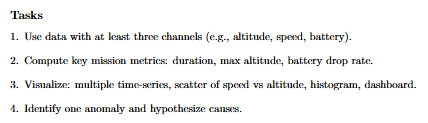


clc;                % Clear command window
clear;              % Remove workspace variables
close all;          % Close figures


time = (0:1:300)';     % Mission lasts 300 seconds

%altitude changes
altitude = 60 + 20*sin(time/30) + randn(size(time))*2;

%speed changes
speed = 12 + 4*sin(time/15) + randn(size(time));

%battery drain
battery = 100 - (0.2*time) + randn(size(time))*0.5;

altitude = fillmissing(altitude,'linear');   % Fill missing altitude values
speed = fillmissing(speed,'linear');         % Fill missing speed values
battery = fillmissing(battery,'linear');     % Fill missing battery values

% Prevent negative battery percentages
battery(battery < 0) = 0;

missionDuration = max(time) - min(time);     % Total mission duration
maxAltitude = max(altitude);                 % Highest altitude reached
avgSpeed = mean(speed);                      % Average speed

% Battery drain rate
batteryDropRate = (battery(1) - battery(end)) / missionDuration;

% Display mission statistics
fprintf('Mission Duration: %.2f seconds\n', missionDuration);

Mission Duration: 300.00 seconds


fprintf('Maximum Altitude: %.2f meters\n', maxAltitude);

Maximum Altitude: 84.74 meters


fprintf('Average Speed: %.2f m/s\n', avgSpeed);

Average Speed: 11.96 m/s


fprintf('Battery Drop Rate: %.3f %% per second\n', batteryDropRate);

Battery Drop Rate: 0.199 % per second



batteryChange = diff(battery);

% Find major drops larger than 2%
anomalyIndex = find(batteryChange < -2);

if isempty(anomalyIndex)
    disp('No battery anomalies detected.')
else
    disp('Battery anomaly detected at times:')
    disp(time(anomalyIndex))
end

Battery anomaly detected at times:


    40
    88
   144
   211
   240
   249



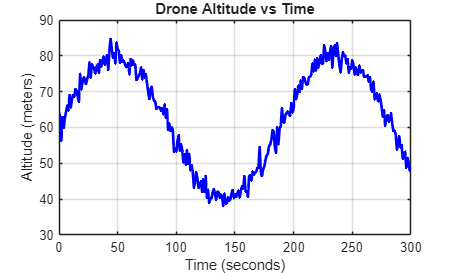


% Figure 1: Altitude vs Time
figure;
plot(time, altitude, 'b', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Altitude (meters)');
title('Drone Altitude vs Time');
grid on;

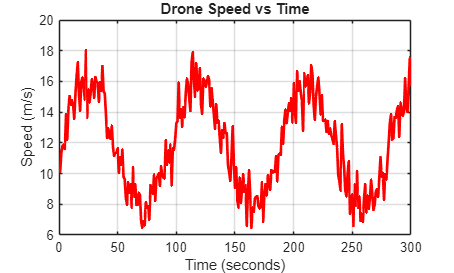


% Figure 2: Speed vs Time
figure;
plot(time, speed, 'r', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Speed (m/s)');
title('Drone Speed vs Time');
grid on;

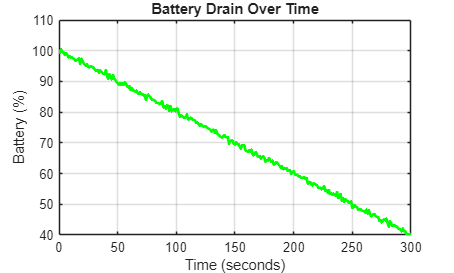


% Figure 3: Battery vs Time
figure;
plot(time, battery, 'g', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Battery (%)');
title('Battery Drain Over Time');
grid on;

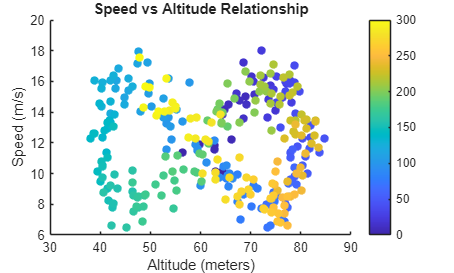


% Figure 4: Speed vs Altitude Scatter Plot
figure;
scatter(altitude, speed, 40, time, 'filled');
xlabel('Altitude (meters)');
ylabel('Speed (m/s)');
title('Speed vs Altitude Relationship');
colorbar;

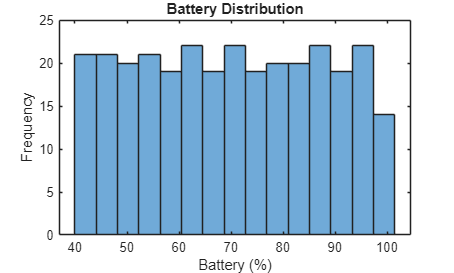


% Figure 5: Battery Histogram
figure;
histogram(battery, 15);
xlabel('Battery (%)');
ylabel('Frequency');
title('Battery Distribution');

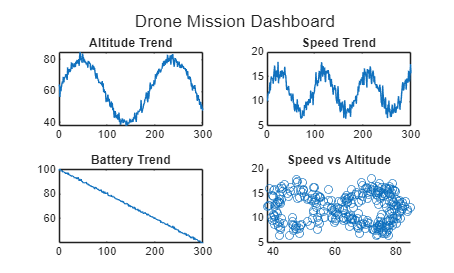


% Dashboard Figure
figure;
tiledlayout(2,2);

nexttile
plot(time, altitude)
title('Altitude Trend')

nexttile
plot(time, speed)
title('Speed Trend')

nexttile
plot(time, battery)
title('Battery Trend')

nexttile
scatter(altitude, speed)
title('Speed vs Altitude')

sgtitle('Drone Mission Dashboard')